# **Elaborato Biomedico**

Il dataset utilizzato in questo progetto è il **"Heart Failure Clinical Records"**, una raccolta di dati clinici anonimizzati. La fonte primaria è l'**UCI Machine Learning Repository**, un archivio accademico di fama mondiale gestito dall'Università della California, Irvine, che garantisce l'affidabilità e la qualità dei dati per scopi di ricerca.

- **URL Fonte Primaria:** [https://archive.ics.uci.edu/dataset/519/heart+failure+clinical+records](https://archive.ics.uci.edu/dataset/519/heart+failure+clinical+records)

- **Autori:** Davide Chicco, Giuseppe Jurman (2020)

- **Pubblicazione Scientifica di Riferimento:** *BMC Medical Informatics and Decision Making*

Il file scaricato, `heart_failure_clinical_records_dataset.csv`, è in formato **CSV (Comma-Separated Values)**. Si tratta di un file di testo semplice dove ogni riga rappresenta un paziente e i valori di ogni colonna (le feature cliniche) sono separati da una virgola. Questo formato è universale e facilmente importabile da quasi tutti i software di analisi dati, incluso MATLAB.

**Contenuto e Scopo del Dataset**

Il dataset contiene **299 record clinici** di pazienti affetti da scompenso cardiaco, raccolti durante il loro periodo di follow-up. Lo scopo principale di questa raccolta dati è fornire una base per lo sviluppo di modelli di machine learning in grado di **predire la mortalità** (l'evento di decesso) basandosi su 12 feature cliniche.

Ogni riga corrisponde a un singolo paziente e contiene una combinazione di dati demografici, abitudini e misurazioni di laboratorio.

Il dataset è composto da 13 colonne. 12 sono le **feature** (predittori) e una è la **variabile target** (l'esito da predire).

## Inizio LiveScript

% Pulisce l'ambiente di lavoro, la command window e chiude tutte le figure
clear; clc; close all;

## Fase 1: Caricamento del file CSV per l'elaborazione

Descrizione Dettagliata dei Campi:

% csvfile = 'heart_failure_clinical_records_dataset.csv';
% inerimento di un controllo di tipo "File Browser" per facilitare l'inserimento del file CSV
csvFile = "D:\Projects\MatLab\Biomedico\heart_failure_clinical_records_dataset.csv";

% Visualizzo il percorso del file CSV appena inserito
fprintf('Il percorso completo del file CSV è il seguente: %s\n', csvFile);

Il percorso completo del file CSV è il seguente: D:\Projects\MatLab\Biomedico\heart_failure_clinical_records_dataset.csv


% Il blocco try catch viene utilizzato per gestire eventuali eccezioni durante
% l'accesso al file

try
    dati = readtable(csvFile);
catch exception
    fprintf('Errore durante il caricamento dei dati: %s\n', exception.message);
end

% Eventuale blocco per cambiare il nome dei campi con la traduzione in inglese
% dati.Properties.VariableNames =  ["Età","Anemia","Creatinina","Diabete","ScompensoCardiaco","PressioneAlta","platelets","serum_creatinine","serum_sodium","sex","smoking","time","death_event"];

% Visualizza le righe della tabella per un'anteprima dei dati
head(dati);

    age    anaemia    creatinine_phosphokinase    diabetes    ejection_fraction    high_blood_pressure    platelets     serum_creatinine    serum_sodium    sex    smoking    time    DEATH_EVENT
    ___    _______    ________________________    ________    _________________    ___________________    __________    ________________    ____________    ___    _______    ____    ___________

    75        0                  582                 0               20                     1               2.65e+05          1.9               130          1        0  

## Istogramma della Distribuzione dell'Età

Questo grafico ci mostra come si distribuisce l'età dei pazienti nel dataset. È utile per capire il profilo demografico del campione (es. se i pazienti sono prevalentemente anziani).

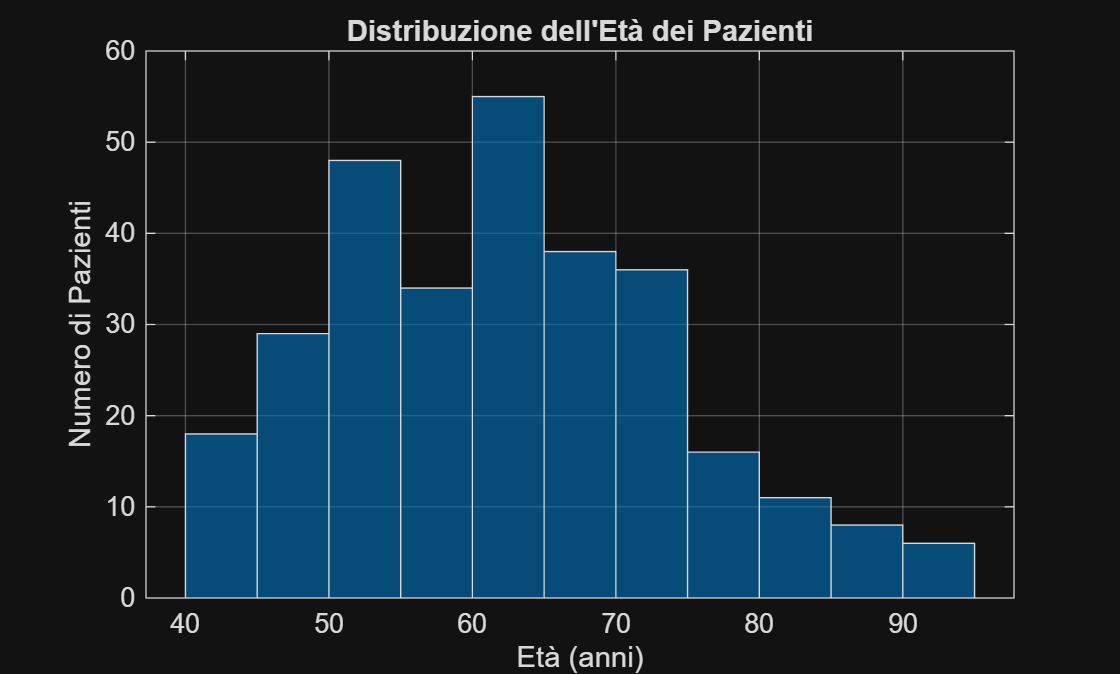

% Inserimento di un controllo ti tipo slider per la modifica in realtime del grafico. 
binWidth = 5;
figure();
histogram(dati.("age"), 'BinWidth', binWidth, 'FaceColor', '#0072BD');
title('Distribuzione dell''Età dei Pazienti');
xlabel('Età (anni)');
ylabel('Numero di Pazienti');
grid on;

## Grafico 2: Box Plot

Il **Box Plot** (o diagramma a scatola) è uno strumento statistico molto utile per visualizzare la distribuzione di un insieme di dati. Mostra rapidamente la mediana, la dispersione, e la presenza di eventuali outlier.

In particolare:

- **Q1 (primo quartile)**: 25% dei dati sono sotto questo valore (limite inferiore della scatola)

- **Mediana (Q2)**: 50% dei dati sono sotto questo valore (linea centrale nella scatola)

- **Q3 (terzo quartile)**: 75% dei dati sono sotto questo valore (linea superiore della scatola)

- **Whiskers**: si estendono fino ai valori minimi e massimi che non sono outlier (linee dette "whiskers")

- **Outlier**: valori molto distanti dalla media, indicati con "+"

L'utilizzo di questa rappresentazione ci auta nel confronto della distribuzione di tre feature cliniche () tra i pazienti sopravvisutti (DEATH_EVENT = 0) e quelli deceduti (DEATH_EVENT = 1).  

Le tre feature selezionabili sono:

- La frazione di eiezione, ovvero la percentuale di sangue pompata dal ventricolo sinistro ad ogni battito. È il principale indicatore della funzionalità cardiaca. Valori bassi indicano un cuore debole.

- **(Feature Chiave)** Il livello di creatinina nel siero (mg/dL). È il principale indicatore della funzionalità renale. Un valore alto indica che i reni non funzionano bene, una condizione spesso associata a scompenso cardiaco grave.

- Il livello di sodio nel siero (mEq/L). Valori bassi (iponatriemia) sono un indicatore di prognosi negativa nello scompenso cardiaco.

La frazione di eiezione è una misura chiave della funzionalità cardiaca. Questo box plot confronta la sua distribuzione tra i pazienti sopravvissuti (DEATH_EVENT = 0) e quelli deceduti (DEATH_EVENT = 1). Ci aiuta a vedere se valori più bassi sono associati a un esito peggiore.

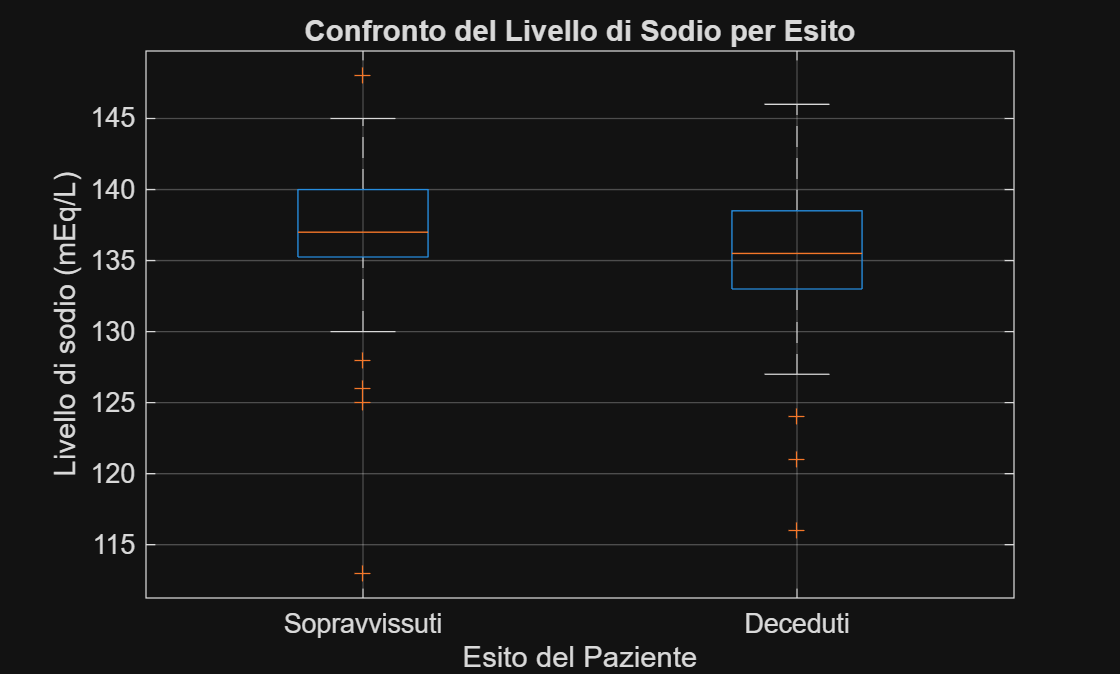

% Inserimento di un controllo di tipo "Drop Down" per la selezione del
% campo da graficare. 
boxItems = {'ejection_fraction','serum_creatinine','serum_sodium','creatinine_phosphokinase'};
boxTitle = {'Confronto della Frazione di Eiezione per Esito','Confronto del Livello di Creatinina per Esito','Confronto del Livello di Sodio per Esito',''};
yLabels = {'Frazione di Eiezione (%)','Livello di creatinina (mg/dL)','Livello di sodio (mEq/L)',''};
value = boxItems(3);

% ritorna l'indice in corrispondenza della selezione effettuata da
% utilizzare per il titolo e l'etichetta verticale del grafico
idx = strcmp(boxItems, value);
figure();
boxplot(dati{:, value}, dati.("DEATH_EVENT"), 'Labels', {'Sopravvissuti', 'Deceduti'});
title(boxTitle(idx));
xlabel('Esito del Paziente');
ylabel(yLabels(idx));
grid on;

## Grafico 3 > Scatter Plot - Creatinina vs Sodio Sierico

Lo **scatter plot** (o **grafico a dispersione**) è uno degli strumenti più potenti e intuitivi per la visualizzazione di relazioni tra due variabili quantitative.

In particolare è utile per:

- Individuare **correlazioni** (positive, negative, nulle)

- Rilevare **outlier**

- Visualizzare **cluster** o gruppi di dati

In questa fase viene utilizzato per esplorare la relazione tra due importanti biomarcatori: la creatinina sierica (indicatore di funzionalità renale) e il sodio sierico. I punti sono colorati in base all'esito (blu=decesso, rosso=sopravvissuto). Questo può rivelare cluster o tendenze che correlano questi valori all'esito clinico.

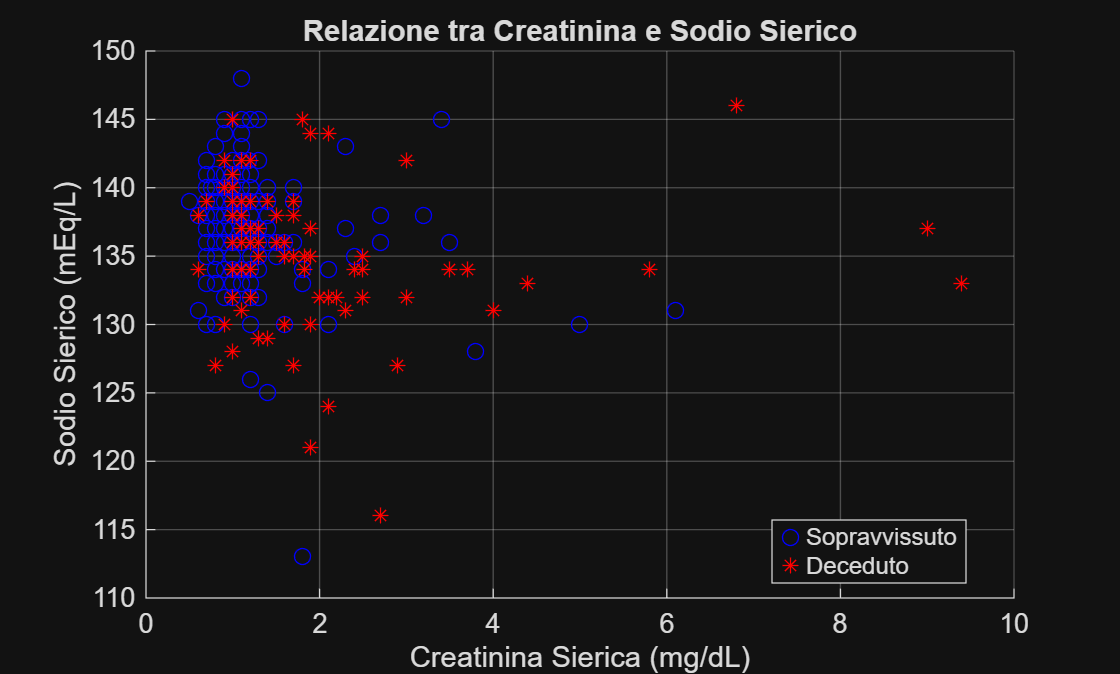

figure();
gscatter(dati.serum_creatinine, dati.serum_sodium, dati.DEATH_EVENT, 'br', 'o*');
title('Relazione tra Creatinina e Sodio Sierico');
xlabel('Creatinina Sierica (mg/dL)');
ylabel('Sodio Sierico (mEq/L)');
legend('Sopravvissuto', 'Deceduto', 'Location', 'best');
grid on;

## Grafico 4 > Matrice di Correlazione (Heatmap)

Il **grafico heatmap** (o mappa di calore) è uno strumento visivo molto potente per la rappresentazione di dati bidimensionali, dove i valori sono codificati attraverso variazioni di colore.

Una heatmap è una **griglia di celle** colorate, dove:

- Ogni cella rappresenta un valore numerico

- Il **colore** indica l’intensità o la grandezza del valore

- È ideale per visualizzare **matrici**, **correlazioni**, **densità**, o **pattern** nei dati

La heatmap visualizza il coefficiente di correlazione di Pearson tra ogni coppia di variabili nel dataset.

Valori vicini a +1 indicano una forte correlazione positiva.

Valori vicini a -1 indicano una forte correlazione negativa.

Valori vicini a 0 (colori intermedi) indicano assenza di correlazione lineare.

È particolarmente utile per vedere quali fattori sono più correlati con la variabile 'DEATH_EVENT'.

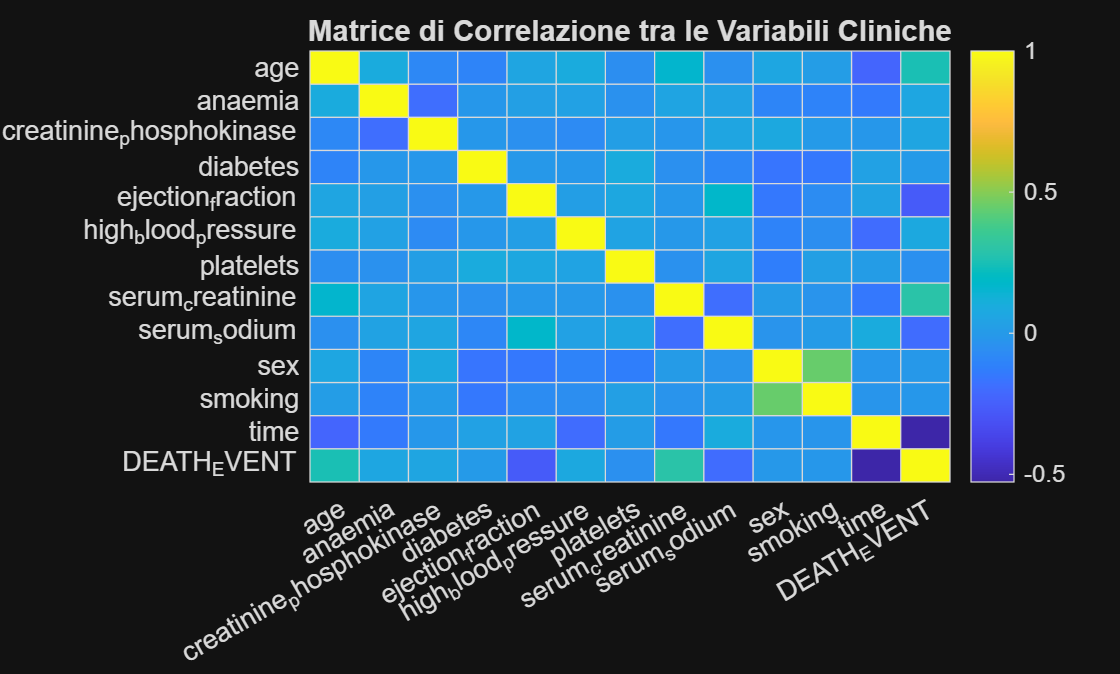

figure();
% Calcoliamo la matrice di correlazione
corrMatrix = corrcoef(table2array(dati));
% Usiamo la funzione heatmap per visualizzarla
heatmap(dati.Properties.VariableNames, dati.Properties.VariableNames, corrMatrix,"Colormap", parula);
title('Matrice di Correlazione tra le Variabili Cliniche');

## Implementazione dell'Algoritmo di previzione (Albero Decisionale)

L'algoritmo usato per la previsione è un **Albero Decisionale** (`fitctree`). Questo modello lavora come un diagramma di flusso intelligente, simile a come un medico potrebbe fare una diagnosi.

**Funzionamento:**

- **Fase di Addestramento (Apprendimento):**

- L'algoritmo analizza tutti i dati del **training set** (i pazienti esaminati).

- Basandosi su una delle feature, cerca la domanda che meglio divide i pazienti in due gruppi: quelli che sono per lo più sopravvissuti e quelli che sono per lo più deceduti. Ad esempio, la domanda migliore potrebbe essere: "**La creatinina sierica del paziente è maggiore di 1.8 mg/dL?**"

- Una volta fatta questa prima divisione, ripete il processo per ciascuno dei due sottogruppi, trovando la domanda successiva migliore. Per esempio, per il gruppo con creatinina alta, la domanda successiva potrebbe essere: "**La frazione di eiezione è inferiore al 30%?**"

- Continua a creare queste "biforcazioni" fino a quando i gruppi finali (le "foglie" dell'albero) sono il più possibile omogenei, contenendo quasi solo pazienti sopravvissuti o quasi solo pazienti deceduti.

- **Fase di Predizione:**

- Quando arriva un nuovo paziente (dal **test set**), i suoi dati vengono "fatti scorrere" lungo questo albero di domande.

- Si parte dalla radice ("La creatinina è > 1.8?"), si segue il ramo "Sì" o "No", e si continua fino ad arrivare a una foglia finale.

- La previsione del modello per quel paziente sarà la classe maggioritaria in quella foglia (se la foglia contiene 10 pazienti deceduti e 2 sopravvissuti, la previsione sarà "Deceduto").

**Spiegazione Dettagliata della Variabile (**`testSetPercentage``)`

La variabile `testSetPercentage` è uno dei parametri più importanti in qualsiasi progetto di machine learning. Definisce la percentuale del dataset originale che viene **messa da parte e riservata esclusivamente per la valutazione finale del modello**.

**Perché è Fondamentale? L'Analogia dell'Esame**

Immagina di dover preparare un esame.

- Il **dataset completo** è il libro di testo.

- Il **training set** (la parte di dati usata per l'addestramento, es. l'80%) sono i capitoli e gli esercizi che studi per imparare.

- Il **test set** (la parte messa da parte, controllata da `testSetPercentage`, es. il 20%) sono le **domande dell'esame finale**, che non hai mai visto prima.

Non puoi valutare la tua vera preparazione rifacendo gli stessi esercizi che hai usato per studiare (otterresti un voto altissimo, ma non sarebbe realistico). L'unico modo per sapere se hai veramente imparato è affrontare domande nuove.

Allo stesso modo, un modello di machine learning imparerebbe a "memoria" i dati di training. Per valutare la sua capacità di **generalizzare** e fare previsioni corrette su dati nuovi e mai visti, abbiamo bisogno del test set.

In sostanza, l'algoritmo impara autonomamente una serie di **regole "se... allora..."** dai dati per creare un percorso diagnostico che porta a una previsione.

In questa sezione, utilizziamo le intuizioni ottenute dalla matrice di correlazione per addestrare un modello predittivo.

Selezione delle Feature (Predittori)

Dalla heatmap (Grafico 4), osserviamo che le variabili con la più forte correlazione (positiva o negativa) con 'DEATH_EVENT' sono:

- **time**: Correlazione fortemente negativa. Più è lungo il periodo di follow-up, minore è la probabilità di decesso registrata.

- **serum_creatinine**: Correlazione positiva. Livelli alti sono un forte predittore di mortalità.

- **ejection_fraction**: Correlazione negativa. Una bassa frazione di predittore di mortalità.

- **age**: Correlazione positiva. L'età avanzata aumenta il rischio.

Selezioniamo queste quattro feature come predittori per il nostro modello.

% Selezione delle feature più promettenti...
predictors = dati(:, {'time', 'serum_creatinine', 'ejection_fraction', 'age'});
response = dati.DEATH_EVENT; % La nostra variabile target
% --- Suddivisione in Training e Test Set ---
% Suddividiamo il dataset per addestrare il modello su una parte dei dati
% (training set) e valutarlo su dati che non ha mai visto (test set).
% Usiamo una suddivisione 80% per il training e 20% per il test.
testSetPercentage = 20;
cv = cvpartition(response, 'HoldOut', testSetPercentage / 100);
idxTrain = training(cv);
idxTest = test(cv);
% Creiamo le tabelle per training e test
XTrain = predictors(idxTrain,:);
YTrain = response(idxTrain,:);
XTest = predictors(idxTest,:);
YTest = response(idxTest,:);

% --- Addestramento di un Albero Decisionale ---
% Gli alberi decisionali sono modelli facili da interpretare e visualizzare.
% Addestriamo il modello usando la funzione 'fitctree'.
disp('Addestramento del modello (Albero Decisionale) in corso...');

Addestramento del modello (Albero Decisionale) in corso...


tic; % Avvia il cronometro per misurare il tempo di addestramento
trainedModel = fitctree(XTrain, YTrain);
trainingTime = toc; % Ferma il cronometro
fprintf('Addestramento completato in %.3f secondi.\n', trainingTime);

Addestramento completato in 0.060 secondi.


% --- Valutazione del Modello ---
% Usiamo il modello addestrato per fare previsioni sul test set.
disp('Valutazione del modello sul test set...');

Valutazione del modello sul test set...


YPred = predict(trainedModel, XTest);
% Calcoliamo l'accuratezza complessiva
accuracy = sum(YPred == YTest) / numel(YTest);
fprintf('Accuratezza del modello: %.2f%%\n', accuracy * 100);

Accuratezza del modello: 88.14%


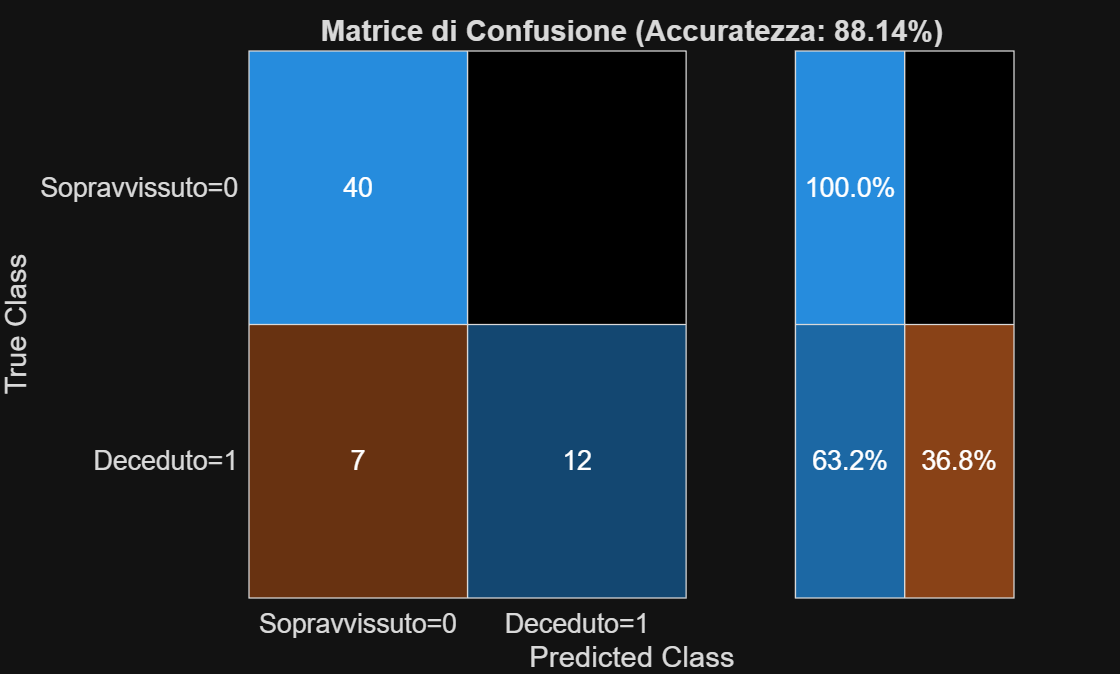

% Visualizziamo la matrice di confusione per un'analisi dettagliata degli errori
figure('Name', 'Performance del Modello di Classificazione');
DisplayLabels = ["Sopravvissuto=0","Deceduto=1"];
confusionchart(YTest, YPred, 'RowSummary', 'row-normalized', 'ColumnDisplayLabels', DisplayLabels, 'RowDisplayLabels', DisplayLabels);
title(sprintf('Matrice di Confusione (Accuratezza: %.2f%%)', accuracy * 100));

cm = confusionmat(YTest, YPred);
% Estraiamo i valori specifici dalla matrice
% cm(riga, colonna) 
veriNegativi = cm(1, 1);
veriPositivi = cm(2, 2);
falsiPositivi = cm(1, 2);
falsiNegativi = cm(2, 1);
% Stampiamo i risultati con una spiegazione
fprintf('\n--- Analisi Dettagliata degli Errori ---\n');


--- Analisi Dettagliata degli Errori ---


fprintf('-> Pazienti sopravvissuti che il modello ha erroneamente predetto come deceduti (Falsi Positivi): %d\n', falsiPositivi);

-> Pazienti sopravvissuti che il modello ha erroneamente predetto come deceduti (Falsi Positivi): 0


fprintf('-> Pazienti deceduti che il modello ha erroneamente predetto come sopravvissuti (Falsi Negativi): %d (ERRORE PIÙ GRAVE)\n', falsiNegativi);

-> Pazienti deceduti che il modello ha erroneamente predetto come sopravvissuti (Falsi Negativi): 7 (ERRORE PIÙ GRAVE)


## Inserimento dei risultati in un DB SQLite

Ho scelto SQLite perché è la soluzione ideale per questo tipo di applicazione: è un database **serverless**, **auto-contenuto** e **basato su un singolo file**. Questo significa che non richiede un server separato e può essere facilmente creato, gestito e distribuito insieme al LiveScript di MATLAB, rendendo il progetto altamente riproducibile.

Lo scopo di questo database non è quello di duplicare i dati clinici originali, ma di fungere da **diario di bordo per gli esperimenti di machine learning** condotti attraverso il LiveScript. Ogni volta che lo script viene eseguito con parametri diversi (es. un modello diverso, una diversa percentuale di test set), i risultati vengono salvati in modo strutturato. Questo permette di tracciare, confrontare e analizzare le performance nel tempo.

L'architettura è basata su un modello relazionale semplice, implementato in un singolo file (`esperimenti_cuore.db`), che contiene due tabelle principali: `Esperimenti` e `Risultati`.

### **Schema Dettagliato delle Tabelle**

#### **Tabella **`Esperimenti`

Questa tabella funge da registro principale. Ogni record rappresenta una singola esecuzione completa dello script di analisi.

- **Scopo:** Tracciare ogni sessione di test, fornendo un contesto generale.

- **Struttura:**

#### **Tabella **`Risultati`

Questa tabella contiene le metriche di performance dettagliate per ogni modello addestrato all'interno di un esperimento.

- **Scopo:** Memorizzare i risultati quantitativi di ogni modello per permettere confronti diretti.

- **Struttura:**

#### **Relazioni tra le Tabelle**

Esiste una relazione **uno-a-molti** tra `Esperimenti` e `Risultati`:

- Un (`1`) record nella tabella `Esperimenti` può essere associato a molti (`N`) record nella tabella `Risultati`.

- Questo modello è flessibile: permette di salvare i risultati di più modelli (es. SVM e Albero Decisionale) sotto lo stesso ID di esperimento, facilitando i confronti diretti all'interno della stessa sessione di test.

La relazione è implementata tramite la **foreign key** `fk_id_esperimento` nella tabella `Risultati`, che fa riferimento alla chiave primaria `id_esperimento` della tabella `Esperimenti`.

#### **Codice SQL per la Creazione (DDL)**

Il seguente codice SQL viene utilizzato per creare la struttura del database.

`-- Creazione della tabella per registrare gli esperimenti`

`CREATE TABLE IF NOT EXISTS Esperimenti (`

`    id_esperimento INTEGER PRIMARY KEY AUTOINCREMENT,`

`    data_esecuzione DATETIME NOT NULL,`

`    descrizione TEXT`

`);`

`-- Creazione della tabella per memorizzare i risultati del modello`

`CREATE TABLE IF NOT EXISTS Risultati (`

`    id_risultato INTEGER PRIMARY KEY AUTOINCREMENT,`

`    fk_id_esperimento INTEGER NOT NULL,`

`    modello_usato TEXT NOT NULL,`

`    percentuale_test_set REAL,`

`    accuratezza REAL,`

`    falsi_positivi INTEGER,`

`    falsi_negativi INTEGER,`

`    FOREIGN KEY (fk_id_esperimento) REFERENCES Esperimenti (id_esperimento)`

`);`

% Nome del file del database

dbfile = 'esperimenti_cuore.db';

% Controlla se il file esiste e imposto la modalità di accesso
% La funzione exist ritorna 0 se il file non esiste o 2 se il file esiste

if exist(dbfile, 'file') == 2
    mode = 'connect'; % il file esiste pertanto la modalità sara 'connect'
else
    mode = 'create';  % il file non esiste pertanto sarà creato un database vuoto con la modalità "create"
end

% Crea la connessione al database SQLite
conn = sqlite(dbfile, mode);

% Creazione della tabella per registrare gli esperimenti
table_name = 'Esperimenti';
sqlQuery = sprintf("CREATE TABLE IF NOT EXISTS %s (" + ...
                        "id_esperimento INTEGER PRIMARY KEY AUTOINCREMENT," + ...
                        "data_esecuzione DATETIME NOT NULL," + ...
                        "descrizione TEXT" + ...
                   ");", table_name);

% Eseguiamo la query per creare/cancellare la tabella nel database
try
    execute(conn, sqlQuery);  
    fprintf('Query eseguita con successo: %s', sqlQuery);
catch exception
    fprintf('Errore durante la creazione della tabella: %s\n', exception.message);
end

Query eseguita con successo: CREATE TABLE IF NOT EXISTS Esperimenti (id_esperimento INTEGER PRIMARY KEY AUTOINCREMENT,data_esecuzione DATETIME NOT NULL,descrizione TEXT);


% Creazione della tabella per memorizzare i risultati del modello
table_name = 'Risultati';
sqlQuery = sprintf("CREATE TABLE IF NOT EXISTS %s (" + ...
                        "id_risultato INTEGER PRIMARY KEY AUTOINCREMENT," + ...
                        "fk_id_esperimento INTEGER NOT NULL," + ...
                        "modello_usato TEXT NOT NULL," + ...
                        "percentuale_test_set REAL," + ...
                        "accuratezza REAL," + ...
                        "falsi_positivi INTEGER," + ...
                        "falsi_negativi INTEGER," + ...
                        "FOREIGN KEY (fk_id_esperimento) REFERENCES Esperimenti (id_esperimento)" + ...
                   ");", table_name);
% Eseguiamo la query per creare/cancellare la tabella nel database
try
    execute(conn, sqlQuery);  
    fprintf('Query eseguita con successo: %s', sqlQuery);
catch exception
    fprintf('Errore durante la creazione della tabella: %s\n', exception.message);
end

Query eseguita con successo: CREATE TABLE IF NOT EXISTS Risultati (id_risultato INTEGER PRIMARY KEY AUTOINCREMENT,fk_id_esperimento INTEGER NOT NULL,modello_usato TEXT NOT NULL,percentuale_test_set REAL,accuratezza REAL,falsi_positivi INTEGER,falsi_negativi INTEGER,FOREIGN KEY (fk_id_esperimento) REFERENCES Esperimenti (id_esperimento));

% --- Inserimento del record dell'esperimento ---
try
    modelSelection = "Albero Decisionale";
    descrizioneEsperimento = sprintf("Test con %s e %d%% di Test Set", modelSelection, testSetPercentage);
    sqlInsertEsperimento = sprintf("INSERT INTO Esperimenti (data_esecuzione, descrizione) VALUES (datetime('now'), '%s')", descrizioneEsperimento);
    exec(conn, sqlInsertEsperimento);
    
    % --- Recupero dell'ID dell'esperimento appena inserito ---
    lastExpID = fetch(conn, "SELECT last_insert_rowid()");
    lastExpID = lastExpID{1,1}; % Estrai il valore numerico
    
    % --- Inserimento del record dei risultati ---
    sqlInsertRisultati = sprintf("INSERT INTO Risultati " + ...
                                     "(fk_id_esperimento, " + ...
                                      "modello_usato, " + ...
                                      "percentuale_test_set, " + ...
                                      "accuratezza, " + ...
                                      "falsi_positivi, " + ...
                                      "falsi_negativi) " + ...
                                 "VALUES (%d, '%s', %.1f, %.4f, %d, %d)", ...
                                 lastExpID, modelSelection, testSetPercentage, accuracy, falsiPositivi, falsiNegativi);
    exec(conn, sqlInsertRisultati);
    
    disp('Risultati salvati con successo nel database.');
catch exception
    fprintf("Errore durante l'inserimento dei record: %s\n", exception.message);
end

Risultati salvati con successo nel database.


try
    sqlSelect = "SELECT " + ...
                     "E.id_esperimento, " + ...
                     "E.data_esecuzione, " + ...
                     "R.modello_usato, " + ...
                     "R.percentuale_test_set, " + ...
                     "R.accuratezza, " + ...
                     "R.falsi_positivi, " + ...
                     "R.falsi_negativi " + ...
                     "FROM Esperimenti E " + ...
                     "JOIN Risultati as R ON E.id_esperimento = R.fk_id_esperimento " + ...
                     "ORDER BY E.data_esecuzione DESC";
        
    % --- Esecuzione della query e recupero dei risultati ---
    storicoEsperimenti = fetch(conn, sqlSelect);
    disp(storicoEsperimenti);
catch exception
    fprintf("Errore durante l'inserimento dei record: %s\n", exception.message);
end

    id_esperimento       data_esecuzione          modello_usato        percentuale_test_set    accuratezza    falsi_positivi    falsi_negativi
    ______________    _____________________    ____________________    ____________________    ___________    ______________    ______________

          6           "2025-08-21 15:13:56"    "Albero Decisionale"             20               0.8814             0                 7       
          5           "2025-08-21 15:05:02"    "Albero Decisionale"             20               0.7966             5                 7       
          4           "2025-08-21 15:04:54"    "Albero Decisionale"             20               0.8305             3                 7       
          3           "2025-08-21 15:04:29"   


% Chiusura del db SQLite
close(conn);

## Fine LiveScript